# Data preparation: cleaning

The data in "biopsies_raw.csv" has not been cleaned:

clear all;
data = readtable('biopsies_raw.csv');

Clean the data and split it ready for training and testing a classifier.

Marks are available for:

- Appropriately addressing: duplicated examples; irrelevant features; missing values [5 marks]

- Identifying and removing the extreme outlier for the "smoothness_mean" feature [3 marks]

- Splitting the data up into an appropriately named training dataset and testing dataset [8 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
summary(data)


Variables:

    id: 570×1 double

        Values:

            Min             8670
            Median    9.0616e+05
            Max       9.1132e+08

    diagnosis: 570×1 cell array of character vectors

    radius_mean: 570×1 double

        Values:

            Min               6.981    
            Median            13.34    
            Max               28.11    
            NumMissing        1        

    texture_mean: 570×1 double

        Values:

            Min             9.71    
            Median        18.835    
            Max            39.28    

    perimeter_mean: 570×1 double

        Values:

            Min            43.79      
            Median         86.21      
            Max            188.5      

    area_mean: 570×1 double

        Values:

            Min          143.5   
            Median      548.75   
            Max           2501   

    


A = unique(data, 'sorted');
summary(A);


Variables:

    id: 569×1 double

        Values:

            Min             8670
            Median    9.0602e+05
            Max       9.1132e+08

    diagnosis: 569×1 cell array of character vectors

    radius_mean: 569×1 double

        Values:

            Min              6.981     
            Median           13.355    
            Max              28.11     
            NumMissing       1         

    texture_mean: 569×1 double

        Values:

            Min            9.71     
            Median        18.84     
            Max           39.28     

    perimeter_mean: 569×1 double

        Values:

            Min            43.79      
            Median         86.24      
            Max            188.5      

    area_mean: 569×1 double

        Values:

            Min          143.5   
            Median       551.1   
            Max           2501   

    


% removes the irrelevant feature id from the table by 
A(:,'id') = [];
summary(A);


Variables:

    diagnosis: 569×1 cell array of character vectors

    radius_mean: 569×1 double

        Values:

            Min              6.981     
            Median           13.355    
            Max              28.11     
            NumMissing       1         

    texture_mean: 569×1 double

        Values:

            Min            9.71     
            Median        18.84     
            Max           39.28     

    perimeter_mean: 569×1 double

        Values:

            Min            43.79      
            Median         86.24      
            Max            188.5      

    area_mean: 569×1 double

        Values:

            Min          143.5   
            Median       551.1   
            Max           2501   

    smoothness_mean: 569×1 double

        Values:

            Min            0.05263     
            Median         0.09592     
           


% removes the missing values from table A
A = rmmissing(A);
summary(A);


Variables:

    diagnosis: 568×1 cell array of character vectors

    radius_mean: 568×1 double

        Values:

            Min           6.981    
            Median       13.355    
            Max           28.11    

    texture_mean: 568×1 double

        Values:

            Min             9.71    
            Median        18.855    
            Max            39.28    

    perimeter_mean: 568×1 double

        Values:

            Min            43.79      
            Median         86.21      
            Max            188.5      

    area_mean: 568×1 double

        Values:

            Min          143.5   
            Median      548.75   
            Max           2501   

    smoothness_mean: 568×1 double

        Values:

            Min            0.05263     
            Median        0.095895     
            Max              0.985     

    compactnes

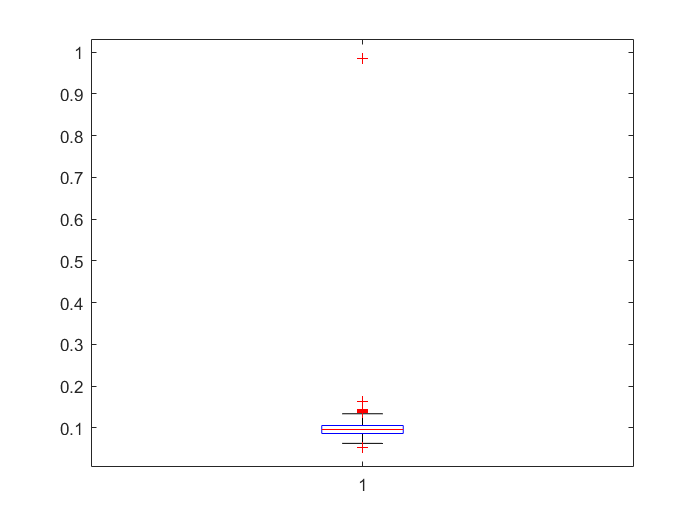


% plotting a box plot with all of the data contained within
%'smoothness_mean'
boxplot(A{:, 'smoothness_mean'});


% removes the data stored in row 149
A(149,:) = [];
summary(A);


Variables:

    diagnosis: 567×1 cell array of character vectors

    radius_mean: 567×1 double

        Values:

            Min           6.981    
            Median        13.37    
            Max           28.11    

    texture_mean: 567×1 double

        Values:

            Min            9.71     
            Median        18.87     
            Max           39.28     

    perimeter_mean: 567×1 double

        Values:

            Min            43.79      
            Median         86.24      
            Max            188.5      

    area_mean: 567×1 double

        Values:

            Min          143.5   
            Median       551.1   
            Max           2501   

    smoothness_mean: 567×1 double

        Values:

            Min            0.05263     
            Median         0.09587     
            Max             0.1634     

    compactnes

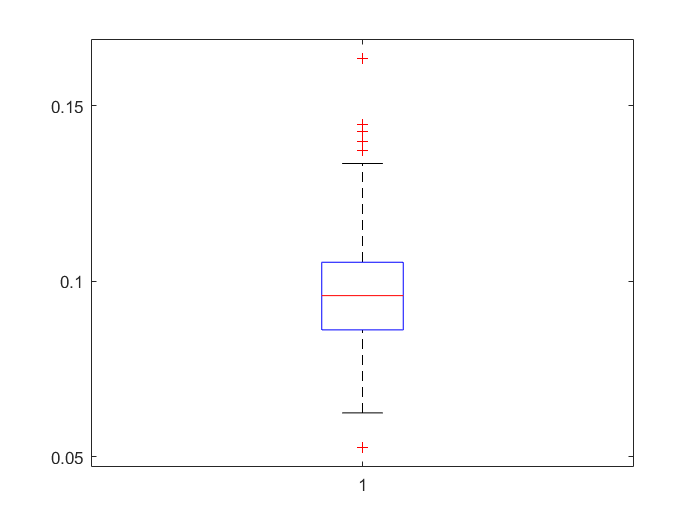


% updated boxplot without the anomaly
boxplot(A{:, 'smoothness_mean'});


nTest = round(0.20 * size(data,1))

nTest = 114


% shuffle the training data
randperm(5)

ans =      1     3     4     5     2



data_shuffled = data(randperm(size(data,1)), :);
test_labels = categorical(A{:,'diagnosis'});
A = data_shuffled(1:1:nTest, :);
data_train = data_shuffled(nTest+1:1:end, :);
size(data_train)

ans =    456    32


A(:,:)

ans = 114×32 table
        id         diagnosis     radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity


% seperating the data
test_labels = categorical(A{:,'diagnosis'});
test_examples = A;
test_examples(:,'diagnosis') = [];

% separate the examples and the labels for the training dataset:
train_labels = categorical(A{:,'diagnosis'});
train_examples = A;
train_examples(:,'diagnosis') = [];

summary(test_labels);

     Benign         71 
     Malignant      43 


summary(train_labels);

     Benign         71 
     Malignant      43 
